OR data

data = readtable("Test1RocketElevation.csv")

data = 546×5 table
      Var1        Var2       Var3      Var4     Var5  
    ________    ________    _______    ____    _______

    {'TFOR'}    0.010254          0     24     0.87821
    {'TFOR'}    0.019287          0     24     0.88358
    {'TFOR'}    0.028564          0     25     0.90682
    {'TFOR'}    0.037598          0     27     0.95525
    {'TFOR'}    0.048096          0     29      1.0357
    {'TFOR'}    0.055908          0     33      1.1768
    {'TFOR'}    0.064941          0     37      1.3194
    {'TFOR'}    0.074219          0     44      1.5605
    {'TFOR'}    0.083252          0     50      1.7961
    {'TFOR'}    0.093506          0     59      2.1118
    {'TFOR'}     0.10156    0.81301     71      2.5396
    {'TFOR'}      0.1106    0.81301     59      2.9294
    {'TFOR'}     0.12085    0.81301     

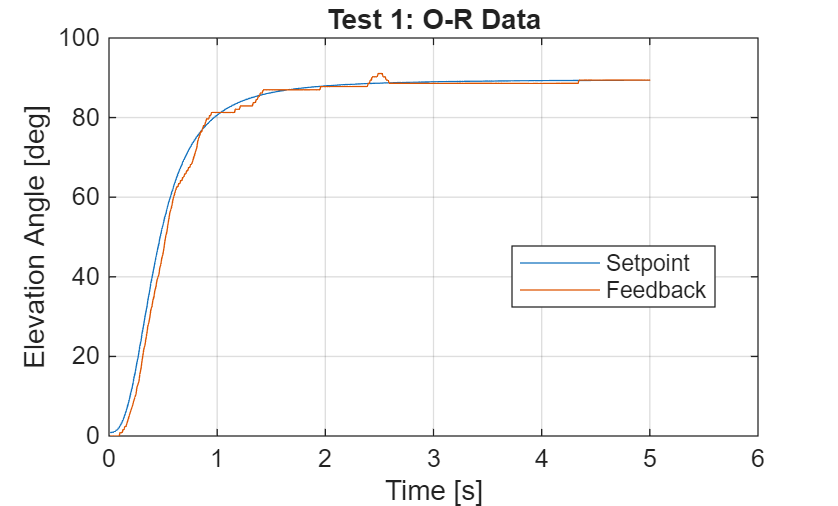

plot(data.Var2,data.Var5)
hold on
plot(data.Var2,data.Var3)

grid on
xlabel("Time [s]")
ylabel("Elevation Angle [deg]")
title("Test 1: O-R Data")
legend(["Setpoint" "Feedback"])
hold off

rmse(data.Var3,data.Var5)

ans = 2.1238

Sin Wave

data = readtable("Test2Sinwave.csv")

data = 1088×5 table
      Var1        Var2        Var3     Var4     Var5 
    ________    _________    ______    ____    ______

    {'TFOR'}    0.0096436         0      0          0
    {'TFOR'}     0.019409         0     15     1.8675
    {'TFOR'}     0.029297         0     29     3.4928
    {'TFOR'}     0.037109         0     44     5.2704
    {'TFOR'}     0.046143         0     55     6.6736
    {'TFOR'}     0.056519         0     70     8.4251
    {'TFOR'}     0.065063         0     85     10.152
    {'TFOR'}     0.074219         0     97     11.678
    {'TFOR'}     0.083252         0    111      13.31
    {'TFOR'}     0.092407         0    124     14.916
    {'TFOR'}      0.10217    1.1111    140     16.755
    {'TFOR'}      0.11121    1.1111    143     18.263
    {'TFOR'}      0.12036    1.1111    156     19.852

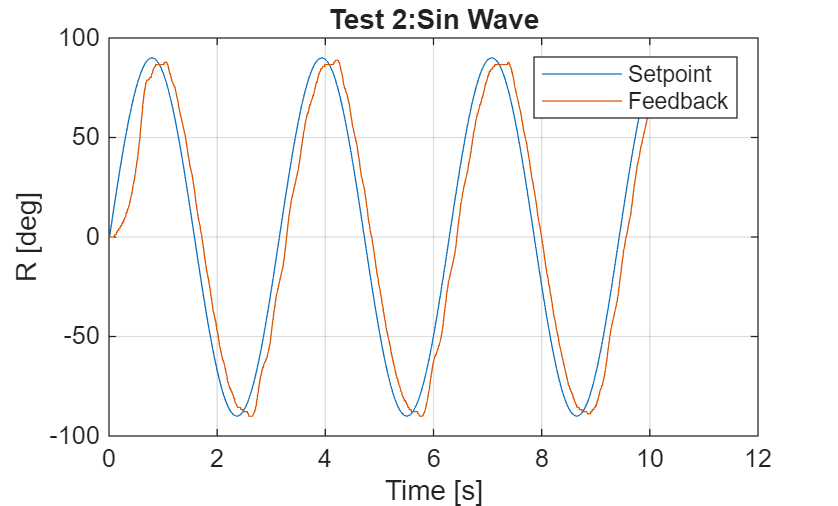

plot(data.Var2,data.Var5)
hold on
plot(data.Var2,data.Var3)

grid on
xlabel("Time [s]")
ylabel("R [deg]")
title("Test 2:Sin Wave")
legend(["Setpoint" "Feedback"])
hold off

rmse(data.Var3,data.Var5)

ans = 18.7566